# **RS-WISP-06-01: Two Impulse Rendezvous Visualization**

**WorkerInSpace**

**Hongseok Kim**

**2/12/2025**

addpath('C:\Users\user\Desktop\Redstone_WISP\RS_WISP_05_RPOD_Functions')

## I. Satellite Orbit Initialization

### I.1 Add Epoch Information

%% Input Parameters

%Initial Epoch Definition
Year = 2025;
Month = 3;
Day = 21;
Hour = 1;
Minute = 0;
Seconds = 0;

% Duration and Steptime
duration = hours(12);
steptime = 15;


startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);
stopTime = startTime + duration;
scenario = satelliteScenario(startTime,stopTime,steptime);

time_vector = scenario.StartTime:seconds(scenario.SampleTime):scenario.StopTime;

### I.2 Run Two-Impluse Rendezvous Function

% Target Information
Target.a = 6880.576;
Target.e = 0.00061350;
Target.i = 97.3726;
Target.RAAN = 298.5678;
Target.AOP = 59.9880;
Target.TA = 300.1964;


% Chaser Information
Chaser.a = 7000.576;
Chaser.e = 0.00061350;
Chaser.i = 97.3726;
Chaser.RAAN = 297.5678;
Chaser.AOP = 59.9880;
Chaser.TA = 299;


%% Main Algorithm

% Change to ECI frame

% rv data of the target wrt ECI
[r_target, v_target] = kepler2ijk_hs(Target.a, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA);

% rc data of the chaser wrt ECI
[r_chaser, v_chaser] = kepler2ijk_hs(Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA);

% Number of Rotation
N = 10;
% Value of Alpha
alpha = 0;

[Delta_v_0, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, tf, t_vector] = cirumNavigation(r_target, v_target, r_chaser, v_chaser, N, alpha);

% Change to rv values


[Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA] = ijk2kepler_hs(r_chaser, v_plus_ECI);


### I.3 Initialize Visualization

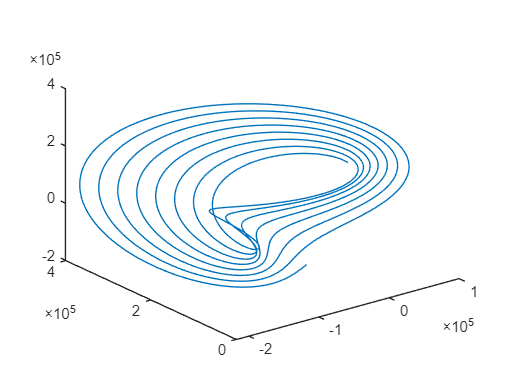

Orbit_propagator = 'SGP4';
sat_name = 'target';

target_satellite = satellite(scenario,Target.a*1000, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA, ... 
                             Name = sat_name, ...
                             OrbitPropagator = Orbit_propagator);


sat_name = 'chaser';
chaser_satellite = satellite(scenario,Chaser.a*1000, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA, ... 
                             Name = sat_name, ...
                             OrbitPropagator  = Orbit_propagator);


satellites_location_information = states(scenario.Satellites);
target_location_info =  satellites_location_information(:,:,1)';
chaser_location_info = satellites_location_information(:,:,2)';

relative_distance = target_location_info - chaser_location_info;
relative_distance_norm = zeros(length(time_vector),1);


for i = 1:length(time_vector)
    relative_distance_norm(i) = norm(relative_distance(i,:));
end

plot3(relative_distance(:,1),relative_distance(:,2),relative_distance(:,3))

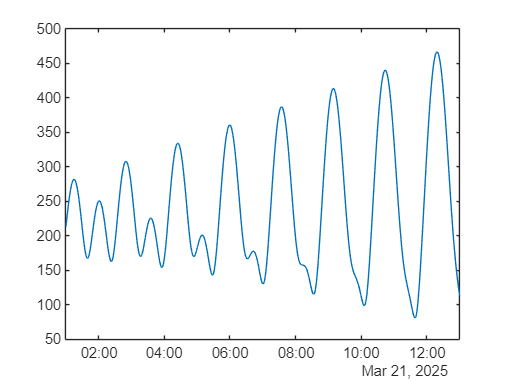


plot(time_vector,relative_distance_norm/1000)


play(scenario)